Main file

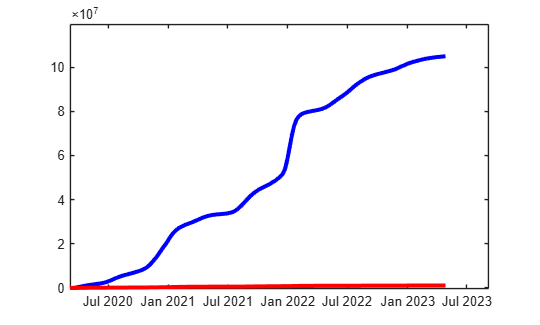

bad_tab_data = readtable("Weekly_United_States_COVID-19_Cases_and_Deaths_by_State_-_ARCHIVED_20261001.csv", "Delimiter", ",");
tab_data = sortrows(bad_tab_data, 1);

badWeekData = tab_data.start_date;
badInfectedData = tab_data.tot_cases;
badDeathsData = tab_data.tot_deaths;
weekData = [];
infectedData = [];
deathsData = [];


for i= 1 : 60: length(badWeekData) - 60
    weekData = [weekData, badWeekData(i)];
    infectedData = [infectedData, sum(badInfectedData(i:i+60))];
    deathsData = [deathsData, sum(badDeathsData(i:i+60))];
end

figure()
plot(weekData, infectedData, 'b', 'LineWidth', 3, 'DisplayName', 'Infected'); hold on
plot(weekData, deathsData, 'r', 'LineWidth', 3, 'DisplayName', 'Dead')
hold off;